clear all,
close all, clc

## Problem

Given,

Name = ['col riv ', 'Fritzi ', 'Hazen ', 'Primo ', 'Raspalse ', 'Hoogo ',  'Balsam ',...
        'Gibec ', 'Beam ', 'Unal ', 'Trichobel ', 'Gaver ', 'Wolterson '];
Aug = [18.3, 13.3, 16.5, 12.6,  9.5, 13.6,  8.1,  8.9, 10.0,  8.3,  7.9,  8.1, 13.4];
Nov = [12.7, 11.0, 15.3, 12.7, 10.5, 15.6, 11.2, 14.2, 16.2, 15.5, 19.9, 20.4, 36.8];

Here,

frst = [210 212 211 211 190 213 212 211 164 209];
scnd = [216 214 162 137 219 218 179 153 152 217];

A1 = scnd;
A2 = frst;

Diff = A2 - A1;
Dff_Ab = abs(Diff);

Now, le'ts assign rank to Diff_Ab

[srt, pos] = sort(Dff_Ab, 'ascend');     % sort Dff_Ab and find the ranks

[~, rnk] = sort(pos);                % put the ranks into position of Dff_Ab

Now, let's find the ranks and +/- sums

len = size(Diff,2);
    T_p = 0; T_n = 0; T_z = 0;          % initializer
    Diff_p = []; Diff_n = [];
    Diff_z = [];                        % initilizers
    rnk_p = []; rnk_n = []; rnk_z = [];
    kp = 1; kn = 1; kz = 1;
for i=1:1:len
    if Diff(i) > 0
        T_p = T_p + rnk(i);      % sums posv's rank
        Diff_p(kp) = Diff(i);    % tracks pos diff
        rnk_p(kp) = rnk(i);      % tracks ranks of psv's
        kp = kp +1;

    elseif Diff(i) < 0 
        T_n = T_n + rnk(i);      % sums ngv's rank
        Diff_n(kn) = Diff(i);    % tracks ngv diff
        rnk_n(kn) = rnk(i);      % tracks ranks of psv's
        kn = kn +1;

    else
        T_z = T_z + rnk(i);      % sums zeros rank
        Diff_z(kz) = Diff(i);
        rnk_z(kz) = rnk(i);      % tracks ranks of psv's
        kz = kz +1;
    end 
end 
T = [T_p, T_n];


Now, rejection or acquisition of Null Hypothesis, **Ho** 

w_st = min(T)

w_st = 16

And, the table fro $w_{\textrm{crt}}$

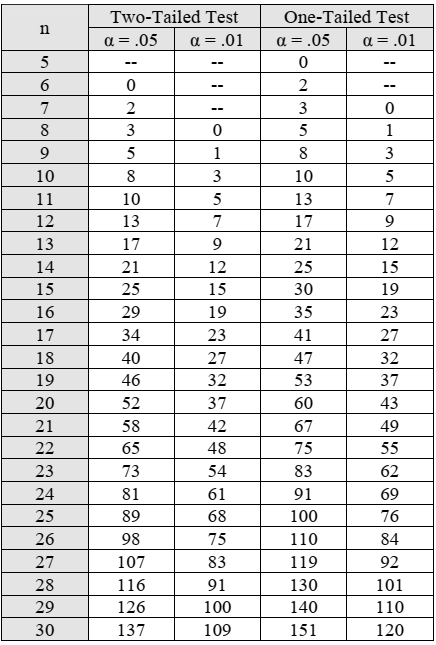

Now, let's do it for two-tailed test

n = length(A1)

n = 10

alf = 0.05;
w_crt = 8;      % ##input

Let's verify-

if w_st <= w_crt
    H = 'Accepted';
else
    H = 'Rejected';
end 
H

H = 'Rejected'

They're not equal, so, Null Hypothesis has to be Rejected